# Lab3 - Image Processing

## Introduction to Monochrome Images

An *image* is the optical representation of objects illuminated by a light source. Since we want to process images using a computer, we represent them as functions of discrete spatial variables. For monochrome (black-and-white) images, a scalar function f(m,n) can be used to represent the light intensity at each spatial coordinate (m, n). Figure 1 illustrates the convention we will use for spatial coordinates to represent images.

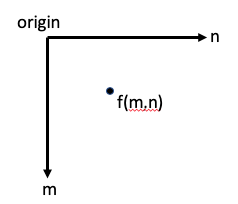

Figure 1: Spatial coordinates used in a digital image representation.

If we assume the coordinates to be a set of positive integers, for example m = 1, . . . , M and n = 1, . . . , N, then an image can be conveniently represented by a matrix.


$$ f(m,n) =
  \left[ {\begin{array}{cccc}
   f(1,1) & f(1,2) & \cdots & f(1,N) \\
   f(2,1) & f(2,2) & \cdots & f(2,N) \\
   \vdots & \vdots &  & \vdots \\
   f(M,1) & f(M,2) & \cdots & f(M,N) \\
  \end{array} } \right] \ \text{.}$$


We call this an M × N image, and the elements of the matrix are known as *pixels*. The pixels in digital images usually take on integer values in the finite range,


$$0 \le f(m,n) \le L_{\text{max}} \ \text{,}$$


where 0 represents the minimum intensity level (black), and $L_{\text{max}}$ is the maximum intensity level (white) that the digital image can take on. The interval [0, $L_{\text{max}}$] is known as a gray scale. In this lab, we will concentrate on 8-bit images, meaning that each pixel is represented by a single byte. Since a byte can take on 256 distinct values, $L_{\text{max}}$ is 255 for an 8-bit image.

In order to process images within Matlab, we need to first understand their numerical representation. Read in the image file 'yacht.tif' . This is an 8-bit monochrome image. Read it into a matrix using myImagUint` = imread(’yacht.tif’);`. Type `whos` to display your variables. Notice under the “Class” column that the myImagUint matrix elements are of type uint8 (unsigned integer, 8 bits). This means that Matlab is using a single byte to represent each pixel. Matlab cannot perform numerical computation on numbers of type uint8, so we usually need to convert the matrix to a floating point representation. Create a double precision representation of the image using myImage` = double(A);`. Again, type `whos` and notice the difference in the number of bytes between myImagUint and myImage. In future sections, we will be performing computations on our images, so we need to remember to convert them to type double before processing them. Display yacht.tif using the following sequence of commands: 

`image(myImage); `

`myImage = double(myImage);`

`colormap(gray(256)); `

`axis(’image’);` 

The image command works for both type uint8 and double images. The colormap command specifies the range of displayed gray levels, assigning black to 0 and white to 255. It is important to note that if any pixel values are outside the range 0 to 255 (after processing), they will be clipped to 0 or 255 respectively in the displayed image. It is also important to note that a floating point pixel value will be rounded down (“floored”) to an integer before it is displayed. Therefore the maximum number of gray levels that will be displayed on the monitor is 255, even if the image values take on a continuous range.

**Put your code here:**

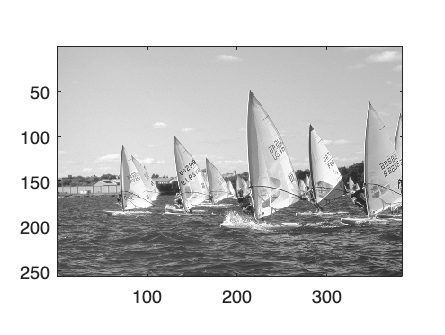

myImagUint = imread('yacht.tif');

image(myImagUint);
myImage = double(myImagUint);
colormap(gray(256));
axis('image')

## Simple Image Operations

Now we will practice some simple operations on the yacht.tif image. Make a horizontally flipped version of the image by reversing the order of each column (use the MATLAB function `fliplr()`). Similarly, create a vertically flipped image (use the MATLAB function f`lipud()`). Display your results. Now, create a “negative” of the image by subtracting each pixel from 255 (here’s an example of where conversion to double is necessary.) Display the result. Finally, multiply each pixel of the original image by 1.5, and display the result.

**Put your code here:**

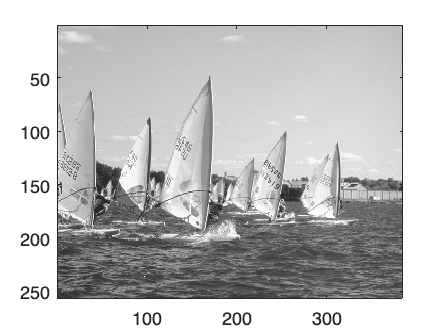

flipImg = fliplr(myImage);
image(flipImg);
colormap(gray(256))

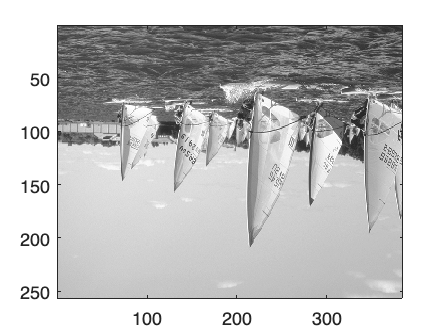


flipVer = flipud(myImage);
image(flipVer);
colormap(gray(256))

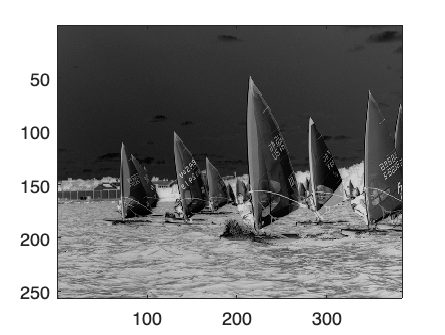


negImg = 255 - myImage;
image (negImg);
colormap(gray(256))

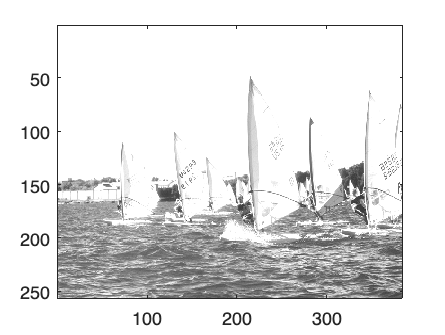


mulImg = myImage .* 1.5;
image (mulImg);
colormap(gray(256))

## Pixel Distributions

### Histogram of an Image

The *histogram* of a digital image shows how its pixel intensities are distributed. The pixel intensities vary along the horizontal axis, and the number of pixels at each intensity is plotted vertically, usually as a bar graph. A typical histogram of an 8-bit image is shown in Fig. 2. 

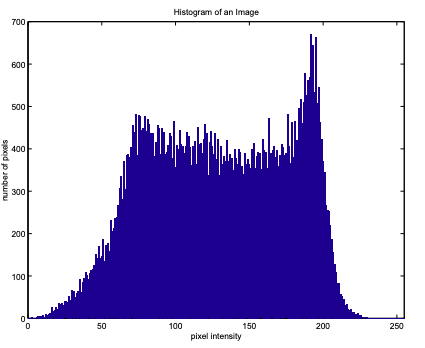

Figure 2. Histogram of an 8-bit image.

Read the image file house.tif into Matlab. Plot a histogram of the pixel values. Label the axes of the histogram and give it a title. You may use Matlab’s `histogram()` function, however that function requires a vector as input. An example of using MATLAB's `histogram()` to plot a histogram of a matrix would be

`x=reshape(A,1,M*N);` 

`histogram(x,'BinLimits',[0,255]);`

where A is an image, and M and N are the number of rows and columns in A. The `reshape()` command is creating a row vector out of the image matrix, and the `histogram()` command plots a histogram with bins centered at [0 : 255].

**Put your code here:**

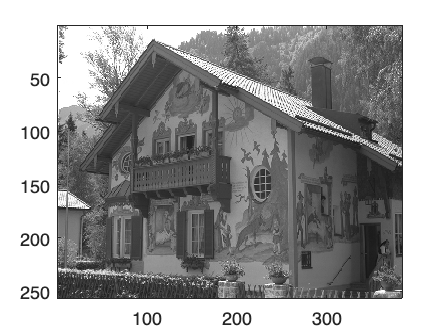

myImagUint = imread('house.tif');
image(myImagUint)

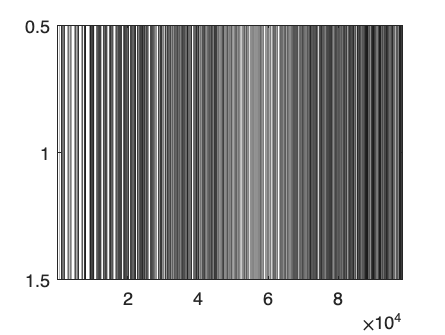

[m,n] = size(myImagUint);
x = reshape(myImagUint, 1, m*n);
image(x)

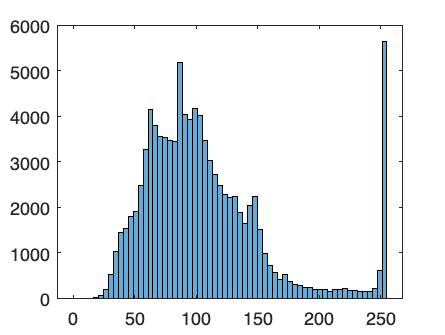

histogram(x, 'BinLimits', [0, 255]);

A pointwise transformation is a function that maps pixels from one intensity to another. An example is shown in Fig. 3. 

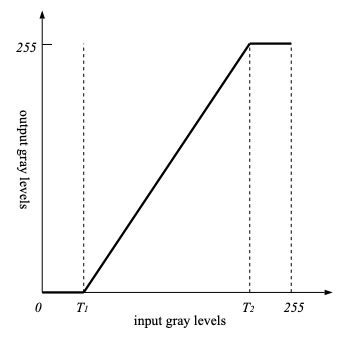

Figure 3: Pointwise transformation of Pixel Values

The horizontal axis shows all possible intensities of the original image, and the vertical axis shows the intensities of the transformed image. This particular transformation maps the “darker” pixels in the range $[0, T_1]$ to a level of zero (black), and similarly maps the “lighter” pixels in $[T_2, 255]$ to white. Then the pixels in the range $[T_1, T_2]$are “stretched out” to use the full scale of [0, 255]. This can have the effect of increasing the contrast in an image.

Pointwise transformations will obviously affect the pixel distribution, hence they will change the shape of the histogram. If a pixel transformation can be described by a oneto-one function, $y = f(x)$, then it can be shown that the input and output histograms are approximately related by the following histogram equation:


$$H_{\text{out}}(y) \approx \frac{H_{\text{in}}(x)}{|f\prime(x)|} \ \text{.}$$


Since x and y need to be integers in the equation above, the evaluation of $x = f^{-1}(y)$ needs to be rounded to the nearest integer.

The pixel transformation shown in Fig. 3 is not a one-to-one function. However, the equation above still may be used to give insight into the effect of the transformation. Since the regions $[0, T_1]$ and $[T_2, 255]$ map to the single points 0 and 255, we might expect “spikes” at the points 0 and 255 in the output histogram. The region [1, 254] of the output histogram will be directly related to the input histogram through the histogram equation. First, notice from $x = f^{-1}(y)$ that the region $[1, 254]$ of the output is being mapped from the region $[T_1, T_2]$ of the input. Then notice that $f\prime(x)$ will be a constant scaling factor throughout the entire region of interest. Therefore, the output histogram should approximately be a stretched and rescaled version of the input histogram, with possible spikes at the endpoints. 

Write a MATLAB function that will perform the pixel transformation shown in Fig. 3. It should have the syntax:

`output = PointTrans(input, T1, T2) ;`

Read the image narrow.tif into MATLAB. Disiplay the image and compute its histogram. The reason the image appears “washed out” is that it has a narrow histogram. Now use your `PointTrans()` function to spread out the histogram using T1 = 70 and T2 = 180. Display the new image and its histogram. 

**Put your PointTrans function code here.** 


% function outImag = PointTrans(inImag, T1, T2)
% %
% % Apply a point transformation to the pixel values of an image
% % Input 
% %       inImag: input image
% %       T1: lower bound for the transformation
% %       T2: upper bound for the transformation
% % Output
% %       outImag: output image
% 

% outImag(find(inImag >= 0 & inImag <= T1)) = 0;
% outImag(find(inImag >= T2 & inImag <= 255)) = 255;
% 
% outImag = inImag * (255/(T2-T1));
% end

**Put your MATLAB code here:**

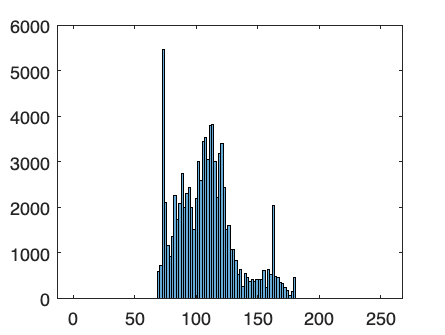

myImagUint = imread("narrow.tif");

histogram(myImagUint, 'BinLimits', [0, 255]);

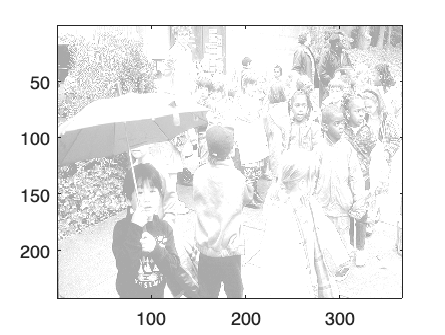

outImag = PointTrans(myImagUint, 70, 180);
image(outImag)

**Answer the following question.**

What has changed in the new image?

**Put your answer here:**

## Gamma ($\gamma$) Correction

The light intensity generated by a physical device can be a nonlinear function of the original signal. For example, a pixel that has a gray level of 200 will not be twice as bright as a pixel with a level of 100. Almost all of the old cathod-ray tube (CRT) computer monitors have a power law response to their applied voltage. For a typical CRT monitor, the brightness of the illuminated phosphors is approximately equal to the applied voltage raised to a power of 2.5. The numerical value of this exponent is known as the gamma (γ) of the CRT. Therefore the power law is expressed as


$$I = V^\gamma$$


where *I* is the pixel intensity and *V* is the voltage applied to the device. If we re-express this equation in terms of pixel values for an 8-bit image, we get the following relationship:


$$y = 255\left(\frac{x}{255}\right)^{\gamma}$$


where *x *is the orignal pixel value and *y *is the pixel value as it appears on the display. This equation is plotted below. Run the code.

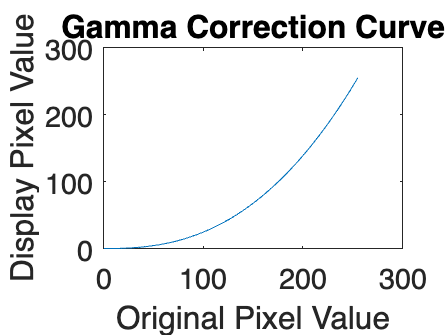

gammaVal = 2.5 ;
origPixVal = linspace(0,255,100) ;
dispPixVal = 255*(origPixVal/255).^gammaVal ;
figure
plot(origPixVal, dispPixVal)
xlabel('Original Pixel Value')
ylabel('Display Pixel Value')
title('Gamma Correction Curve')
set(gca,'fontsize',16)

In order to achieve the correct reproduction of intensity, the display nonlinearity must be compensated by a process known as γ-correction. Images that are not properly corrected usually appear too light or too dark. If the value of γ is available, then the correction process consists of applying the inverse of the display's gamma power law. This is a straightforward pixel transformation, as discussed previously.

With modern LED displays, gamma correction is usually not required. The variation in pixel intensity is achieved by rapidly turning the LED on and off generally using pulse width modulation. There is much nonsense on the web about gamma correction and relating it to human perception. Human perception is another layer of complexity that should not be related to gamma correction which relates to nonlinearities in display hardware. We will return to the issue of human perception again when we talk about color appearance models in a different lab.

In order to demonstrate the gamma-correction, read into MATLAB the image file 'dark.tif'. Assume the gamma value is 2.2 (e.g., typical of LCDs) for a given display device. Apply a gamma correction pixel transformation to this image to fix the display. More specifically, do the following: (1) read in the image; (2) create a figure to display the image; (3) create a function G`ammCorr(myImage, gammaVal)` that returns a new Image with the gamma correction pixel transformation applied.; (4) apply your G`ammCorr() `function to the 'dark.tif' image; (5) display the new image with the gamma correction applied. 

**Put your GammCorr function code here.** 

**Put your MATLAB code here:**

myImage = imread('dark.tif')

myImage = 384×256 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0

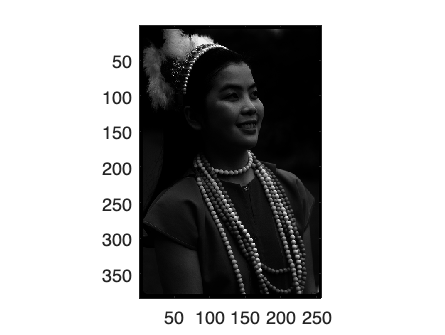

figure
image(myImage)
colormap(gray(256))
axis('image')

gammaVal = 2.2

gammaVal = 2.2000

newImage = GammCorr(double(myImage), gammaVal)

newImage =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

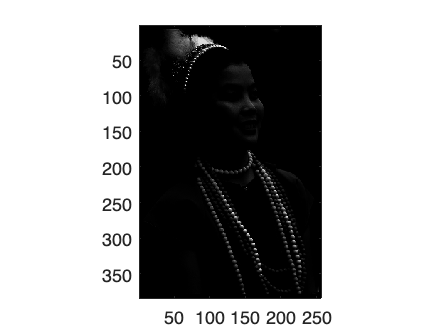

figure
image(newImage)
colormap(gray(256))
axis('image')

## Image Enhancement Filters

Sometimes, we need to process images to improve their appearance. In this section, we will discuss two fundamental image enhancement techniques: image *smoothing* and *sharpening*.

### Image Smoothing

Smoothing operations are used primarily for diminishing spurious effects that may be present in a digital image, possibly as a result of a poor sampling system or a noisy transmission channel. Lowpass filtering is a popular technique for image smoothing. 

Some filters can be represented as a 2-D convolution of an image $f(m,n)$ with the filter’s impulse response $h(m,n)$:


$$g[m,n] = \sum_{k=-\infty}^{\infty}\sum_{l=-\infty}^{\infty}f[k,l]h[m-k,n-l] \ \text{.}$$


Some typical lowpass filter impulse responses are shown in Fig. 4, where the center element corresponds to $h[0,0]$. Notice that the terms of each filter sum to one. This prevents amplification of the DC component of the original image.

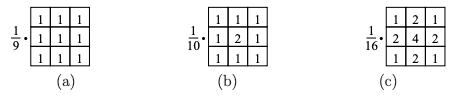

Figure 4: The Impulse response of some lowpass filters for image smoothing are shown.

Note that the image filters are two-dimensional. We can plot these filters in MATLAB using the `stem3()`function as shown below.

Run the code below.

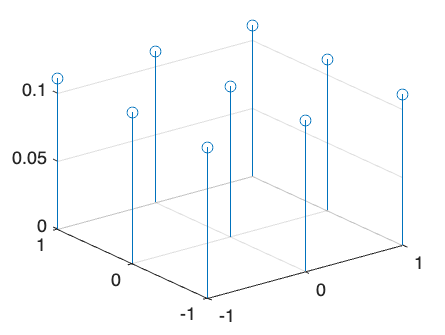

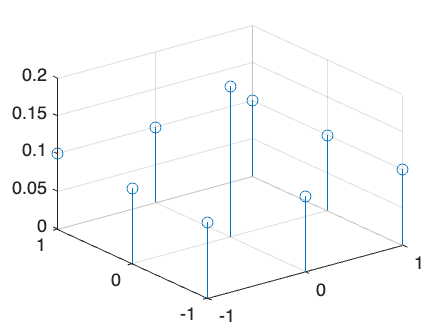

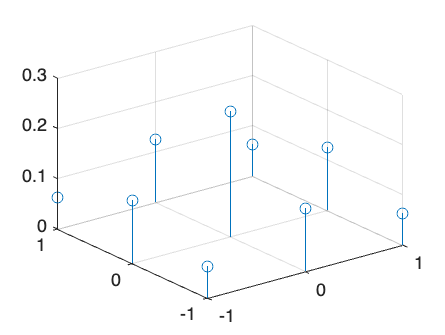

myFilt1 = ones(3,3)*(1/9) ;

myFilt2 = ones(3,3) ; myFilt2(2,2) = 2 ;
myFilt2 = myFilt2*(1/10) ;
myFilt3(1,:) = [1 2 1] ;
myFilt3(2,:) = [2 4 2] ;
myFilt3(3,:) = [1 2 1] ;
myFilt3 = myFilt3*(1/16) ;
Xax = [-1 0 1] ;
Yax = [-1 0 1] ;
figure
stem3(Xax,Yax,myFilt1)
figure
stem3(Xax,Yax,myFilt2)
figure
stem3(Xax,Yax,myFilt3)

#### Frequency Response

As with 1D filters, we can speak about the 2D filter's frequency response. The maths follows in a similar manner to that for 1D systems. We will rehearse this mantra below. An important subclass of two-dimensional linear shift-invariant systems are those for which the input and output satisfy a linear constant-coefficient difference equation of the form:


$$\sum_{k=0}^{M_1}\sum_{l=0}^{N_1}a_{kl}y[m-k,n-l] = \sum_{k=0}^{M_2}\sum_{l=0}^{N_2}b_{kl}x[m-k,n-l] \ \text{.}$$


We again impose the additional initial rest constraint that if $x[m,n]= 0$ for all *m* and *n*, then $y[m,n] = 0$ for all *m* and *n*. As with a 1D system, the 2D LCCDE can correspond to a causal or non-causal system. A causal system simply implies that the current pixel value $y[m_0,n_0]$ only depends on previously known information, which would be any of the pixels $x[m,n]$and all pixels of $y[m,n]$ with $[m,n] < [m_0,n_0]$.

Similarly as for 1D systems, the response to a complex exponential of the form:


$$x[m,n] = e^{j\,\omega_1 m}e^{j\,\omega_2 n}$$


can be computed. Let $h[m,n]$ be the 2D impulse response, then the convolution sum gives:


$$y[m,n] = \sum_{k=-\infty}^{\infty}\sum_{l=-\infty}^{\infty}h[k,l]e^{j\,\omega_1(m-k)}e^{j\,\omega_2(n-l)$$



$$y[m,n] = \sum_{k=-\infty}^{\infty}\sum_{l=-\infty}^{\infty}h[k,l]e^^{-j\,\omega_1k}e^{-j\,\omega_2\,l}e^{j\,\omega_1m}e^{j\,\omega_2 n}$$



$$y[m,n] = H(e^{j\,\omega_1},e^{j\,\omega_2})e^{j\,\omega_1m}e^{j\,\omega_2\,n} \ \text{.}$$


Thus, we have the frequency response for the filter $h[m,n]$ is given by:


$$H(e^{j\,\omega_1},e^{j\,\omega_2}) = \sum_{k=-\infty}^{\infty}\sum_{l=-\infty}^{\infty}h[k,l]e^^{-j\,\omega_1k}e^{-j\,\omega_2\,l} \ \text{.}$$


This transformation is known as the 2D DTFT. The inverse 2D DTFT is given by:


$$h[m,n] = \frac{1}{4\pi^2}\int_{-\pi}^{\pi}\int_{-\pi}^{\pi}H(e^{j\,\omega_1},e^{j\,\omega_2})e^{j\,\omega_1\,m}e^{j\,\omega_2\,n}d\omega_1d\omega_2 \ \text{.}$$


We can calculate the frequency response of an FIR image filter h[m,n] in MATLAB using matrix vector multiplication for the summations as shown below (similarly to what we did for the 1D DTFT).

Run the code below.

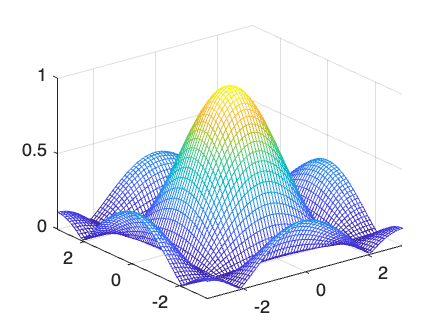

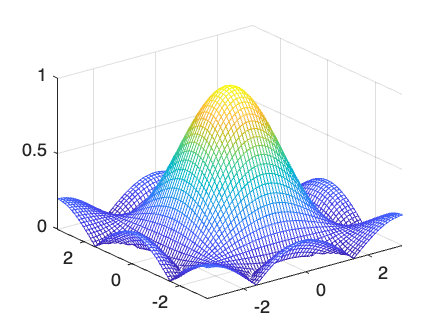

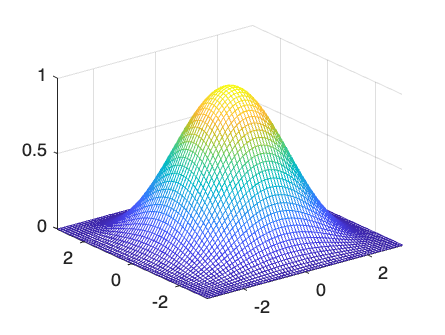

% Set the filter indices
mIndex = (-1:1) ; nIndex = (-1:1) ;

% Set the number of frequency points
K = 32 ; L = 32 ;
% Create the two exponential matrices
kIndex = (-K:K) ; lIndex = (-L:L) ;
W1mat = (mIndex' * kIndex) ;
W2mat = (nIndex.' * lIndex) ;
W1mat = (exp(-1j*pi/K)) .^ W1mat ;
W2mat = (exp(-1j*pi/L)) .^ W2mat ;
% Calculate Freq. Resp. of myFilt1
% Sum along k
HfqMat1 = myFilt1.' * W1mat ;
% Sum along l
HfqMat1 = HfqMat1.' * W2mat ;
% Plot the Frequency Response
figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat1))
colormap('default')
% Calculate Freq. Resp. of myFilt2
% Sum along k
HfqMat2 = myFilt2.' * W1mat ;
% Sum along l
HfqMat2 = HfqMat2.' * W2mat ;
% Plot the Frequency Response
figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat2))
colormap('default')
% Calculate Freq. Resp. of myFilt3
% Sum along k
HfqMat3 = myFilt3.' * W1mat ;
% Sum along l
HfqMat3 = HfqMat3.' * W2mat ;
% Plot the Frequency Response
figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat3))
colormap('default')


Lowpass filtering can reduce additive noise, but at the same time it blurs the image. Hence, blurring is a major limitation of lowpass filtering. Images can also be smoothed by nonlinear filtering, such as mathematical morphological processing. Median filtering is one of the simplest morphological techniques, and is useful in the reduction of impulsive noise. The main advantage of this type of filter is that it can reduce noise while preserving the detail of the original image. In a median filter, each input pixel is replaced by the median of the pixels contained in a surrounding window. This can be expressed by:


$$g[m,n] = \text{median}\{f[m-k,n-l]\}\text{,}\ (k,l)\in W$$


where $W$is a suitably chosen window. Median filters are generally useful in removing 'salt and pepper' type noise. 

### Smoothing Exercise

#### Gaussian Filter

Among the many spatial lowpass filters, the Gaussian filter is of particular importance. This is because it results in very good spatial and spectral localization characteristics. The Gaussian filter has the form:


$$h[m,n] = C\exp\left(-\frac{m^2+n^2}{2\sigma^2}\right)$$


where $\sigma^2$, known as the variance, determines the size of passband area. Usually the Gaussian filter is normalized by a scaling constant C such that the sum of the filter coefficients is unity:


$$\sum_{m,n}h[m,n] = 1\ \text{.}$$


Write a MATLAB function to create a normalized Gaussian filter that is centered on the origin (the center element of your matrix should be h[0,0]). Note that this filter is both separable and symmetric, meaning $h[m,n] = h[m]h[n]$ and $h[m]=h[-m]$. Use the syntax:

`hFilt = GaussFilter(Npts, var)`

where Npts determines the size of the filter, var is the variance, and hFilt is an NxN filter. Note that for this filter to be symmetrically centered on zero, N will have to be an odd number. Using MATLAB code similar to that above, compute the frequency response of a 7 × 7 Gaussian filter with $\sigma^2=1$. Use K = L = 32. Plot the magnitude of the frequency response using the mesh command. Plot it over the range $[-\pi,\pi] \text{x}[-\pi,\pi]$and label the axes.

**Put your GaussFilter function here.**

**Put your MATLAB code here:**

hFilt = GaussFilter(7,1) ;
% Set the filter indices
mIndex = (-3:3) ; nIndex = (-3:3) ;
% Set the number of frequency points
K = 32 ; L = 32 ;
% Create the two exponential matrices:
kIndex = (-K:K) ; lIndex = (-L:L) ;
W1mat = (mIndex' * kIndex) ;
W2mat = (nIndex.' * lIndex) ;
W1mat = (exp(-1j*pi/K)) .^ W1mat ;
W2mat = (exp(-1j*pi/L)) .^ W2mat ;
% Calculate Freq. Resp. of myFilt1
% Sum along k
Hfq = hFilt.' * W1mat ;
% Sum along l
Hfq = Hfq.' * W2mat ;
% Plot the Frequency Response
figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(Hfq))
colormap('default')
xlabel('\omega_x')
ylabel('\omega_y')
title('Filter Frequency Response')
set(gca,'FontSize',20)

### Median Filter

Write a MATLAB function to implement a 3 × 3 median filter (without using the medfilt2 command). Use the syntax 

`outImage = MedianFilter(inImage);`

For convenience you do not have to alter the pixels on the border of the input image.

**Put your MedianFilter code here:**

### Test Your Two Filters

Read in the image files race.tif, noise1.tif and noise2.tif . The noise images are versions of race.tif that have been degraded by additive white Gaussian noise and “salt and pepper” noise, respectively. Read them into Matlab, and display them using image. Filter each of the noisy images with both the 7 × 7 Gaussian filter ($\sigma^2=1$) and the 3 × 3 median filter. You can filter the images with your Gaussian filter using the MATLAB command `filter2()`. Your M`edianFilter() `function already works directly on the image. Display the results of the filtering, and place a title on each figure. Compare the filtered images with the original noisy images. When comparing the images, place the images into a 2 x 3 subplot grid with the first column being the original images, the second column being the images filtered with the Gaussian filter, and the third column being the images filtered with the Median filter.

**Put your MATLAB code here:**

### Image Sharpening

Image sharpening techniques are used primarily to enhance an image by highlighting details. Since fine details of an image are the main contributors to its high frequency content, highpass filtering often increases the local contrast and sharpens the image. Some typical highpass filter impulse responses used for contrast enhancement are shown in Fig. 5. 

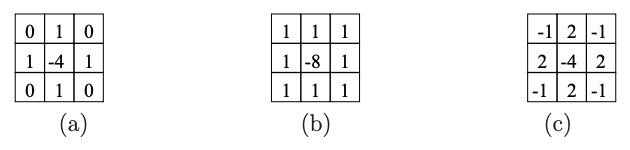

Figure 5: Impulse responses for highpass filters useful for image sharpening.

We can plot these filters in MATLAB using the `stem3()`function as shown below.

Run the code below.

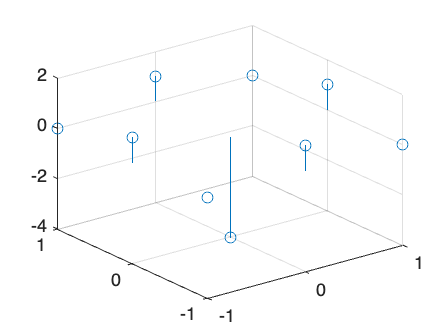

myFilt1 = [0 1 0;1 -4 1; 0 1 0] ;
myFilt2 = ones(3,3) ;

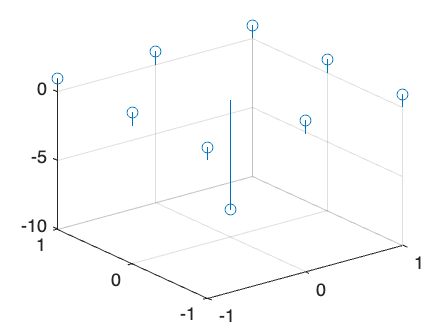

myFilt2(2,2) = -8 ;
myFilt3 = [-1 2 -1;2 -4 2;-1 2 -1] ;

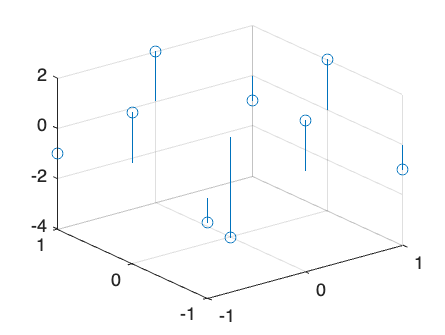

Xax = [-1 0 1] ;
Yax = [-1 0 1] ;

figure
stem3(Xax,Yax,myFilt1)
figure
stem3(Xax,Yax,myFilt2)
figure
stem3(Xax,Yax,myFilt3)

We can calculate the frequency response of the highpass FIR sharpening filters h[m,n] in MATLAB using the 2D DTFT as shown below.

Run the code below.

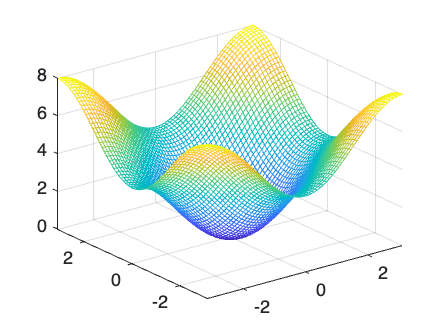

% Set the filter indices
mIndex = (-1:1) ; nIndex = (-1:1) ;
% Set the number of frequency points
K = 32 ; L = 32 ;
% Create the two exponential matrices
kIndex = (-K:K) ; lIndex = (-L:L) ;
W1mat = (mIndex' * kIndex) ;
W2mat = (nIndex.' * lIndex) ;
W1mat = (exp(-1j*pi/K)) .^ W1mat ;
W2mat = (exp(-1j*pi/L)) .^ W2mat ;
% Calculate Freq. Resp. of myFilt1
% Sum along k
HfqMat1 = myFilt1.' * W1mat ;
% Sum along l
HfqMat1 = HfqMat1.' * W2mat ;
% Plot the Frequency Response

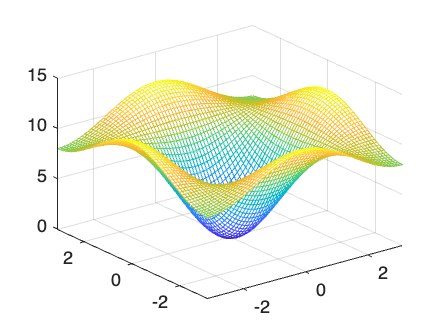

figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat1))
colormap('default')
% Calculate Freq. Resp. of myFilt2
% Sum along k
HfqMat2 = myFilt2.' * W1mat ;
% Sum along l
HfqMat2 = HfqMat2.' * W2mat ;
% Plot the Frequency Response

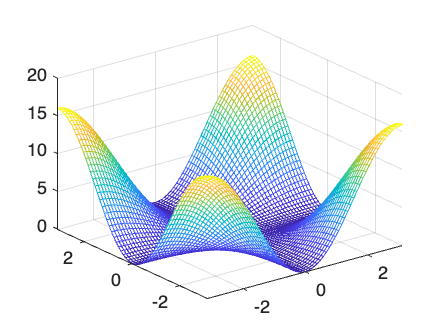

figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat2))
colormap('default')
% Calculate Freq. Resp. of myFilt3
% Sum along k
HfqMat3 = myFilt3.' * W1mat ;
% Sum along l
HfqMat3 = HfqMat3.' * W2mat ;
% Plot the Frequency Response

figure
mesh(kIndex*(pi/K),lIndex*(pi/L),abs(HfqMat3))
colormap('default')

Highpass FIR filters will generally enhance the contrast of images, however, it will generally make the image more noisy. Noise in images often contributes to the high frequency content and highpass filtering can accentuate this noise.

### Sharpening Exercise

In this section, we will introduce a sharpening filter known as an *unsharp mask*. This type of filter subtracts out the “unsharp” (low frequency) components of the image, and consequently produces an image with a sharper appearance. Thus, the unsharp mask is closely related to highpass filtering. The process of unsharp masking an image $f[m,n]$ can be expressed by:


$$g[m,n] = \alpha f[m,n] - \beta \left[f[m,n] \ast h[m,n]\right]\ \text{,}$$


where $h[m,n]$ is a lowpass filter and $\alpha$ and $\beta$ are positive constants such that $\alpha - \beta = 1$. 

Analytically calculate the frequency response of the unsharp mask filter in terms of $\alpha$, $\beta$, and $H(e^{j\,\omega_1},e^{j\,\omega_2})$.

**Put your analytical answer here using Latex insert:**

Using your `GaussFilter()` function, create a 5 × 5 Gaussian filter with $\sigma^2=1$. Use Matlab to compute the frequency response of an unsharp mask filter with $\alpha = 5,\ \beta = 4$, and the Gaussian filter as $h[m,n]$. Use the analytical expression you calculated above. Plot the magnitude of this response in the range $[-\pi,\pi] \text{x}[-\pi,\pi]$ using the `mesh()` function, and label the axes.

**Put your code here:**

Read the image "blur.tif" into MATLAB. Apply the unsharp mask filter with the parameters specified above to this image using:


$$g[m,n] = \alpha f[m,n] - \beta \left[f[m,n] \ast h[m,n]\right]\ \text{.}$$


Use `image()` to view the original and processed images.

**Put your code here:**

**Answer the following question:**

Describe any positive and negative effects of the filtering that you observe. Discuss the influence of the α and β parameters.

**Put your answer here:**

**Appendix:**

function outImag = PointTrans(inImag, T1, T2)
%
% Apply a point transformation to the pixel values of an image
% Input 
%       inImag: input image
%       T1: lower bound for the transformation
%       T2: upper bound for the transformation
% Output
%       outImag: output image

outImag(find(inImag >= 0 & inImag <= T1)) = 0;
outImag(find(inImag >= T2 & inImag <= 255)) = 255;

outImag = inImag * (255/(T2-T1));
end

function newImage = GammCorr(myImage, gammaVal)
%
% Apply a gamma correction to an image
% Input
%      myImage: input image
%      gammaVal: gamma correction value
% Output
%      newImage: gamma corrected image

newImage = zeros(size(myImage));

for i = 1:numel(myImage)
  newImage(i) = 255*(myImage(i)/255).^gammaVal;
end

end